## Initialize Images

img1 = imread("OrionNebula1.png");
img2 = imread("OrionNebula2.png");
img3 = imread("OrionNebula3.png");
img4 = imread("OrionNebula4.png");
img5 = imread("OrionNebula5.png");

## Average Images

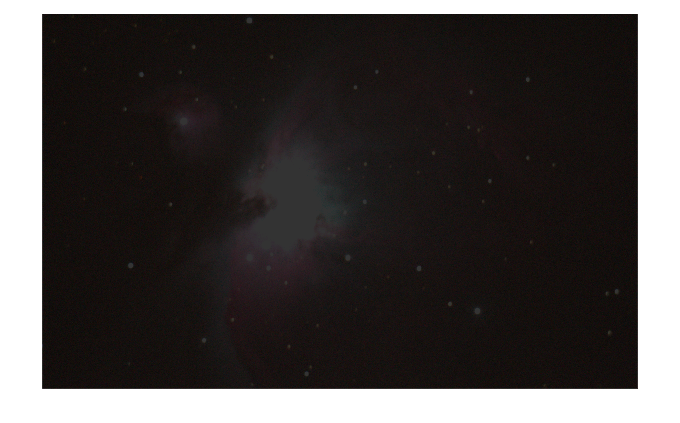

avgImage = (img1+img2+img3+img4+img5)/5;
imshow(avgImage)

## Converting to Double

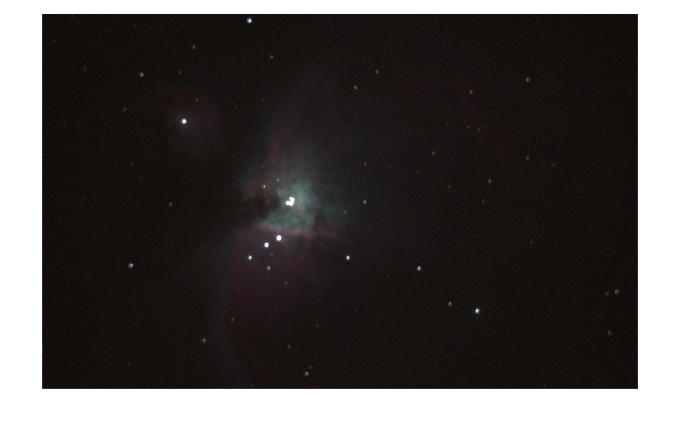

avgImage = (im2double(img1)+im2double(img2)+im2double(img3)+im2double(img4)+im2double(img5))/5;
imshow(avgImage)

## Compare the Average Image & One of the images

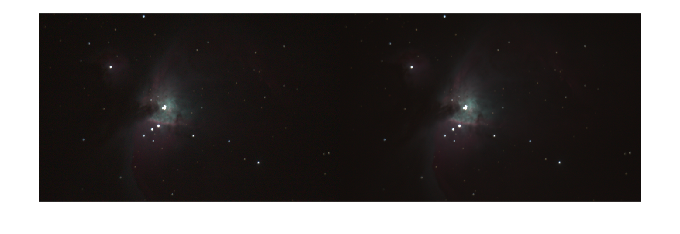

montage({img1, avgImage})

## Convert Back to uint8

avgImage = im2uint8(avgImage);
imshow(avgImage);

## Compare Double & Uint8 Average

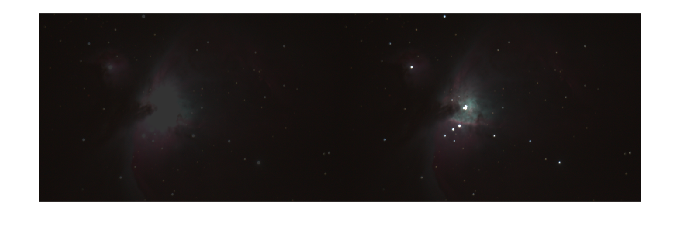

avgIU = (img1+img2+img3+img4+img5)/5;
avgID = (im2double(img1)+im2double(img2)+im2double(img3)+im2double(img4)+im2double(img5))/5;
montage({avgIU, avgID});

## Compare Converted Uint8 from Double & Uint8

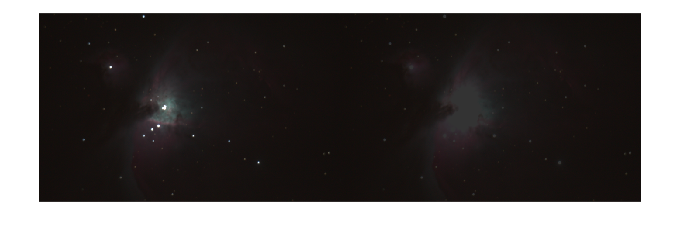

montage({avgImage, avgIU});

The difference in clarity arises due to the precision involved when using **double** versus **uint8** during calculations.

**1. When using double**:

- Double is a 64-bit data type that allows for floating-point precision, meaning it can handle fractional values and much more accurate calculations. This ensures that small differences in pixel values are preserved during operations like averaging.

- When you convert the final result back to **uint8**, the values are rounded to the nearest integer, but the calculations have already been done with high precision, resulting in a more accurate representation

**2. When using uint8 directly**:

- uint8 is an 8-bit integer type, which only allows values between 0 and 255. Any operations performed within this range may lead to rounding errors, and small differences between pixel values can be lost. Additionally, if the sum of values exceeds 255 during operations like addition, clipping occurs, leading to loss of information.

## Converting to Gray Scale

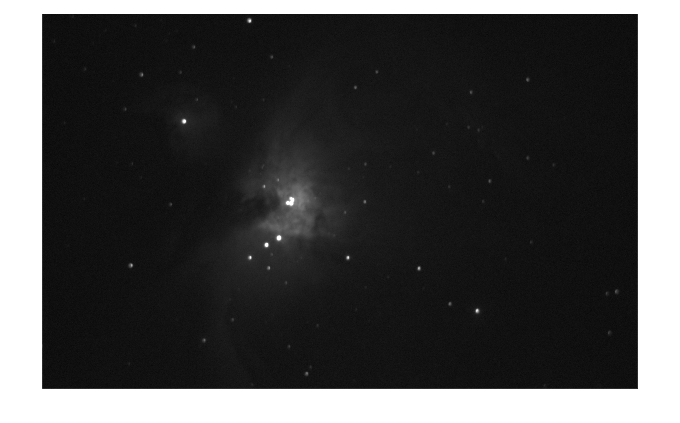

imGray = im2gray(avgImage);
imshow(imGray);

## Reducing Image Resolution by Scale Factor

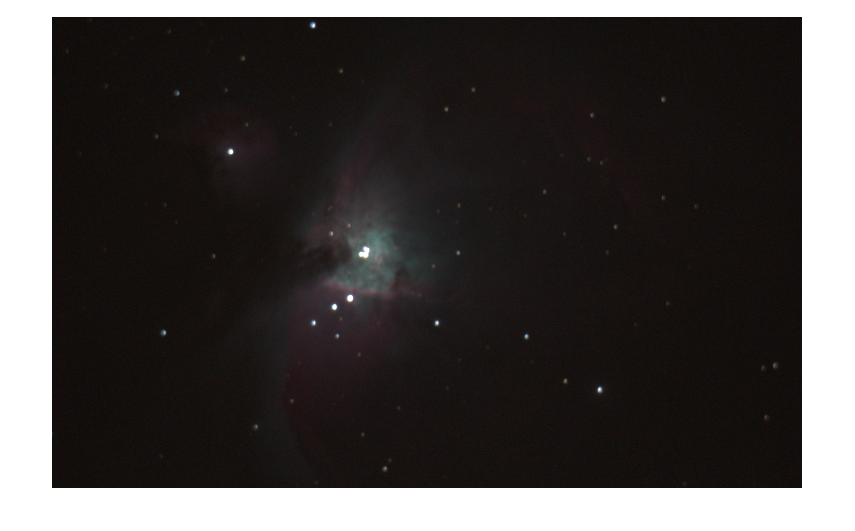

avgIreduced = imresize(avgImage, 0.75); 
imshow(avgIreduced)

## Reducing Image Resolution with Specific Size

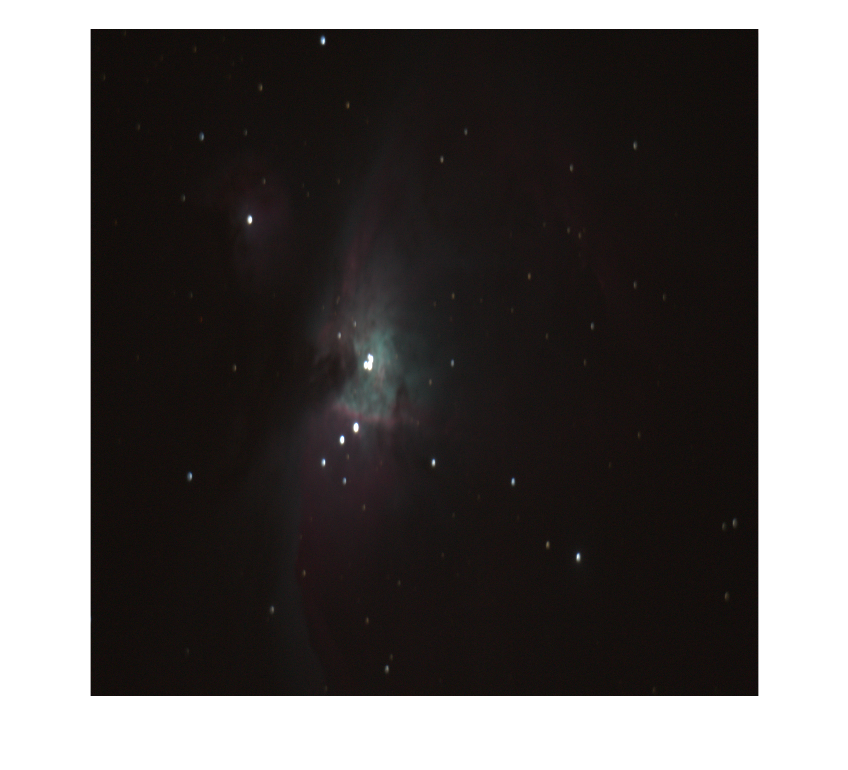

avgIsquare = imresize(avgImage, [2000, 2000]);
imshow(avgIsquare)

## Rotating Images

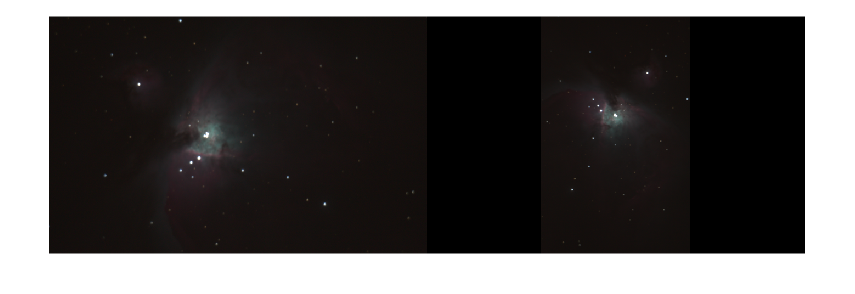

avgIrotated = imrotate(avgImage, -90); 
montage({avgImage, avgIrotated})

**NOTE: **Negative value is **clockwise **rotation

## Saving the Image with .png

imwrite(avgImage, "averageOrion.png")

**PNG File Format: **

- Lossless compression

- Large file size

## Saving the Image with .jpg

imwrite(avgImage, "averageOrionQ80.jpg", "Quality", 80) % With 80 percent quality
imwrite(avgImage, "averageOrionQ100.jpg", "Quality", 100) % With 100 percent quality

**JPG File Format**

- Lossy compression

- Small file size

**NOTE: **Even with 100% quality, its still using "lossy compression".